clc
clear 

# **CODE PERFORMANCE, STATISTICAL ANALYSIS**

### **IMPORTING DATA ABOUT DISTANCES FROM GOLD TOKENS.**

You can change the type of data by setting the 'random' bool variable

- random = false. The statistical analysis will be performed with data coming from a map where silver token were standardly placed.

- random = true. The statistical analysis will be performed with data coming from a map where silver token were randomly placed.

n_data = 9; 

random = true; %% MODIFY THIS

% Setting the path where I stored all the data. 
if (random == false)
    str_sol = "Solution\distances from_gold_solution(";
    str_my = "MY\distances from_gold(";
    my_str_time = "MY\time(";
    sol_str_time = "Solution\time_solution(";
else 
    str_sol = "Solution_RANDOM\distances from_gold_solution(";
    str_my = "MY_RANDOM\distances from_gold(";
    my_str_time = "MY_RANDOM\time(";
    sol_str_time = "Solution_RANDOM\time_solution(";
end

str = ").txt";
solutions_cell = cell(1, n_data + 1);
my_cell =  cell(1, n_data + 1);
% Filling up two cells containing all the data, one for my solution and the
% other one for the professor sulution
for k = 0:n_data
  solutions_cell{k+1} = importdata(str_sol + num2str(k) + str); % Professor solution
  my_cell{k+1} = importdata(str_my + num2str(k) + str);         % My solution
end

**COMPUTING MEAN AND STANDARD DEVIATION OF THE DISTANCES** **FOR EACH CODE EXECUTION**

my_std_array = zeros(1, n_data);
my_mean_array = zeros(1,n_data);
sol_std_array = zeros (1, n_data);
sol_mean_array = zeros(1,n_data);
for k = 0:n_data
    my_std_array(k+ 1) = std(my_cell{k + 1});               % Array with distances standard deviation about my solution
    sol_std_array(k + 1) = std(solutions_cell{k + 1});      % Array with distances standard deviation about the professor solution
    my_mean_array(k + 1) = mean(my_cell{k + 1});            % Array with means about my solution
    sol_mean_array(k + 1) = mean(solutions_cell{k + 1});    % Array with means about the professor solution
end

**COMPUTING THE TOTAL MEAN OF THE DISTANCES**

my_MEAN = mean(my_mean_array);      % Mean of means. I called it 'Total Mean'
my_MEAN = my_MEAN';
sol_MEAN = mean(sol_mean_array);    % Mean of means.
sol_MEAN = sol_MEAN';

**PLOTTING DATA WITH *****"barwitherr"***** FUNCTION**

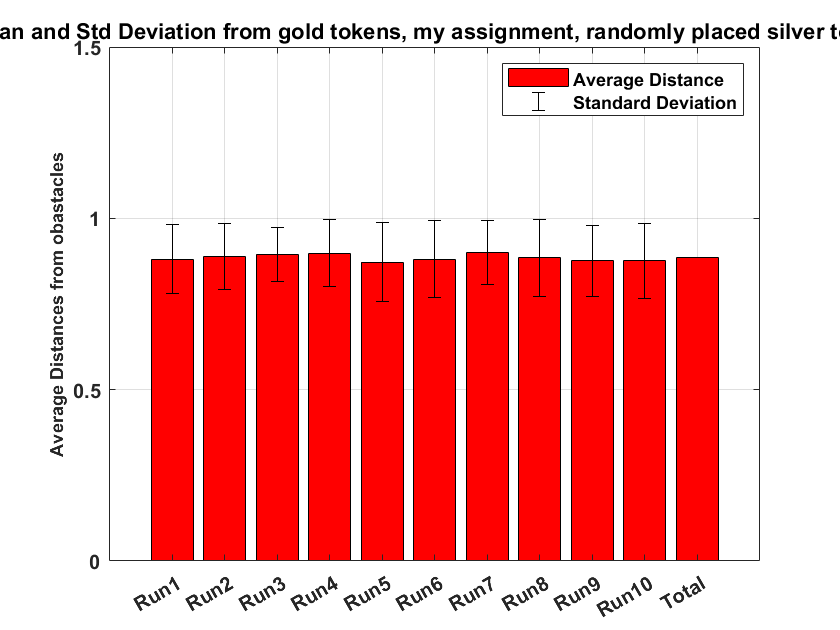

% Bar plotting data with standard deviation. MY SOLUTION. 
figure
y = [my_mean_array, my_MEAN];          
errY = [my_std_array, 0];              
h = barwitherr(errY, y);    
if random == false
    title("Mean and Std Deviation from gold tokens, my assignment, standardly placed silver tokens")
else
    title("Mean and Std Deviation from gold tokens, my assignment, randomly placed silver tokens")
end
set(gca,'XTickLabel',{'Run1','Run2','Run3', 'Run4', 'Run5', 'Run6', 'Run7','Run8', 'Run9', 'Run10', 'Total'},'fontweight','bold','fontsize',10);
legend('Average Distance', 'Standard Deviation');
ylabel('Average Distances from obastacles','fontweight','bold','fontsize',9);
ylim([0 1.5])
grid on
set(h(1),'FaceColor', 'r');

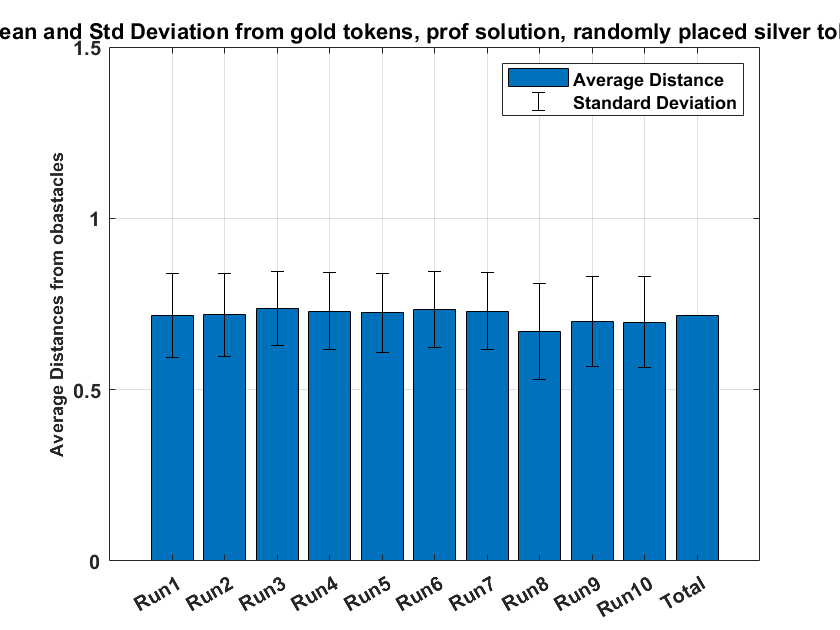

% Bar plotting data with standard deviation. PROFESSOR SOLUTION.   
y2 = [sol_mean_array, sol_MEAN];             
errY2 = [sol_std_array, 0];         
h = barwitherr(errY2, y2); 
if random == false
    title("Mean and Std Deviation from gold tokens, prof solution, standardly placed silver tokens")
else
    title("Mean and Std Deviation from gold tokens, prof solution, randomly placed silver tokens")
end
set(gca,'XTickLabel',{'Run1','Run2','Run3', 'Run4','Run5', 'Run6','Run7', 'Run8','Run9','Run10', 'Total'} ,'fontweight','bold','fontsize',10);
legend('Average Distance', 'Standard Deviation');
ylabel('Average Distances from obastacles','fontweight','bold','fontsize',9);
grid on
ylim([0 1.5])

### **IMPORTING DATA ABOUT TIME REQUIRED TO FINISH THE CIRCUIT**

my_cell_data = cell(1, n_data + 1);     
sol_cell_data = cell(1, n_data + 1);
my_time_matrix = zeros(5, n_data); 
sol_time_matrix = zeros(5, n_data); 
% Filling up two cell containing the number of laps and the time taken for
% each lap. 
% Filling up two matrices containing the only the time taken for
% each lap. 
for k = 0:n_data
  % My solution. 
  my_cell_data{k+ 1} = importdata(my_str_time + num2str(k) + str);
  my_time_matrix(:, k + 1) = my_cell_data{k+1}(: ,2);
  % Professor solution
  sol_cell_data{k+ 1} = importdata(sol_str_time + num2str(k) + str);
  sol_time_matrix(:, k + 1) = sol_cell_data{k+1}(: ,2);
end

my_mean_time = mean(my_time_matrix, 2);     % Mean time for each lap. My solution. 
my_mean_time_4run = mean(my_time_matrix);   % Mean time for each code execution. My solution
sol_mean_time = mean(sol_time_matrix, 2);   % Mean time for each lap. Professor solution. 
sol_mean_time_4run = mean(sol_time_matrix); % Mean time for each code execution. Professor solution.

**PLOTTING DATA ABOUT TIME TAKEN FOR EACH LAP**

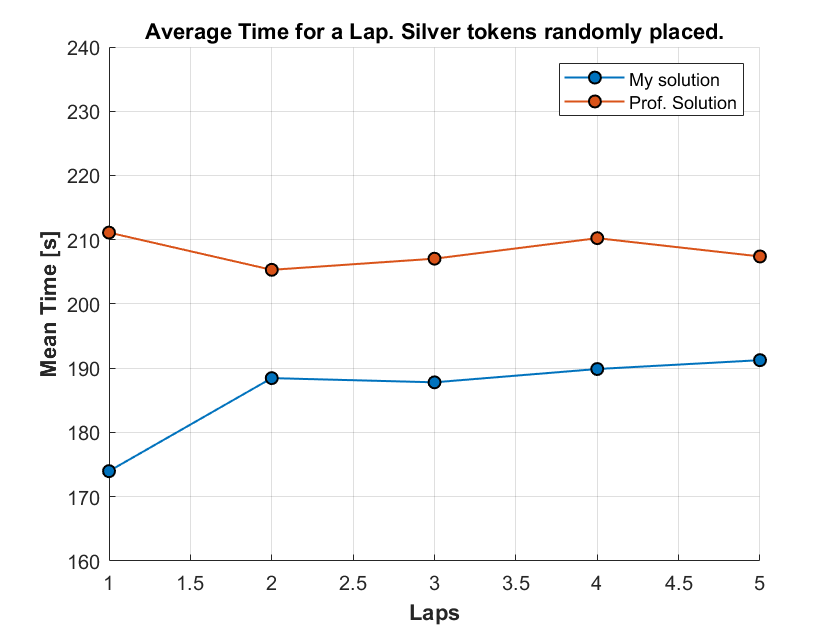

% Plotting data. 
figure
hold on 
plot(my_mean_time, 'Marker', 'o' ,'LineStyle','-', 'LineWidth', 1, 'MarkerEdgeColor','k', 'MarkerFaceColor','#0072BD')
plot(sol_mean_time, 'Marker', 'o' ,'LineStyle','-', 'LineWidth', 1, 'MarkerEdgeColor','k', 'MarkerFaceColor','#D95319')
legend("My solution", "Prof. Solution")
ylabel("Mean Time [s]", FontWeight="bold")
xlabel("Laps", FontWeight="bold")
grid on
ylim([160 240])
if random == false
    title("Average Time for a Lap. Silver tokens standardly placed.")
else
    title("Average Time for a Lap. Silver tokens randomly placed.")
end

**T-TEST FOR TIME DATA**

my_time_vector = my_time_matrix(:);     % reshaping to a column vector
sol_time_vector = sol_time_matrix(:);   % reshaping to a column vector

Null hypotesys **Ho**: The mean time of the professor's solution is equal to the mean time of my solution. 

The alternative hypotesys **Ha** is that the professor's solution mean is grater than my solution mean. 

[h, p, ci, stats] = ttest2(sol_mean_time_4run, my_mean_time_4run, 'Tail', 'Right')

h = 1

p = 0.0200

ci =     4.7628       Inf


stats = struct with fields:
    tstat: 2.2147
       df: 18
       sd: 22.1592


Result:

**h = 1**, therefore ttest2 **rejects the null hypothesis** at the default 5% significance level. 

**So, the professor's solution takes a greater amount of time in completing a lap with respect to my solution. **

**T-TEST FOR DISTANCES DATA**

% T-test for distances time taken for each lap. 
my_dist_col = zeros(1, n_data);
my_dist_col = [my_cell{1}; my_cell{2}; my_cell{3}; my_cell{4}; my_cell{5}; my_cell{6}; my_cell{7}; my_cell{8}; my_cell{9}];                                                                 % reshaping to a column vector
sol_dist_col = [solutions_cell{1}; solutions_cell{2}; solutions_cell{3}; solutions_cell{4}; solutions_cell{5}; solutions_cell{6}; solutions_cell{7}; solutions_cell{8}; solutions_cell{9}]; % reshaping to a column vector


Null hypotesys **Ho**: The mean distance from obstacles of the professor's solution is equal to the mean distance from obstacles of my solution. 

The alternative hypotesys **Ha** is that my solution distance mean is grater than professor's solution mean. 

[h, p, ci, stats] = ttest2(my_mean_array, sol_mean_array, 'Tail', 'right')

h = 1

p = 3.8261e-15

ci =     0.1572       Inf


stats = struct with fields:
    tstat: 23.1419
       df: 18
       sd: 0.0164


Result:

**h = 1**, therefore ttest2 **rejects the null hypothesis** at the default 5% significance level. 

**So, the my solution robot keeps a grater distance from obstacles with respect to the professor robot. **

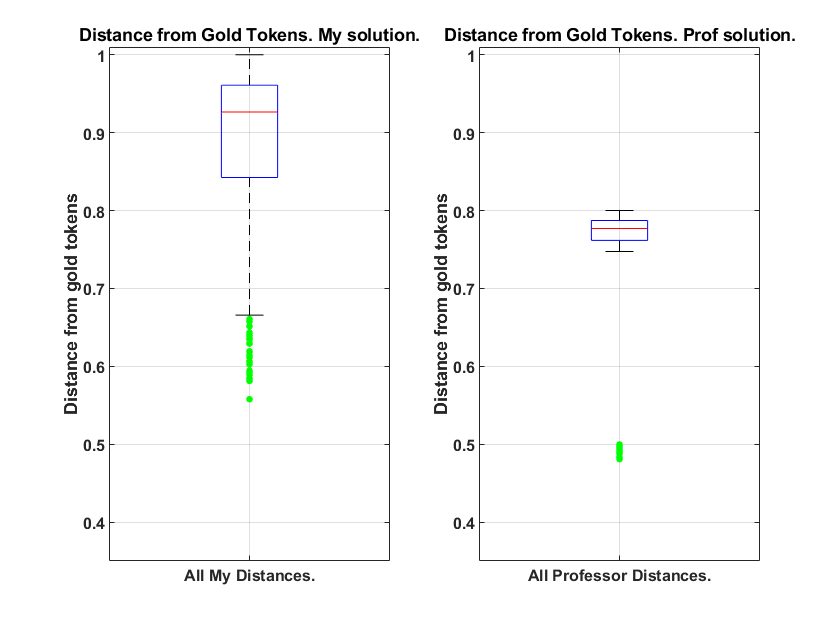

figure
subplot(1, 2, 1)
boxplot(my_dist_col, 'Symbol', 'g.', 'OutlierSize', 10, 'Widths', 0.2,  'Whisker',1.5);
ylim([0.35 1.01])
grid on
ylabel("Distance from gold tokens")
set(gca,'XTickLabel',{'All My Distances.'},'fontweight','bold','fontsize',8);

title("Distance from Gold Tokens. My solution.")


subplot(1, 2, 2)
boxplot(sol_dist_col, 'Symbol', 'g.', 'OutlierSize', 10, 'Widths', 0.2,  'Whisker',1.5);
ylim([0.35 1.01])
grid on
ylabel("Distance from gold tokens")
set(gca,'XTickLabel',{'All Professor Distances.'},'fontweight','bold','fontsize',8);
title("Distance from Gold Tokens. Prof solution.")

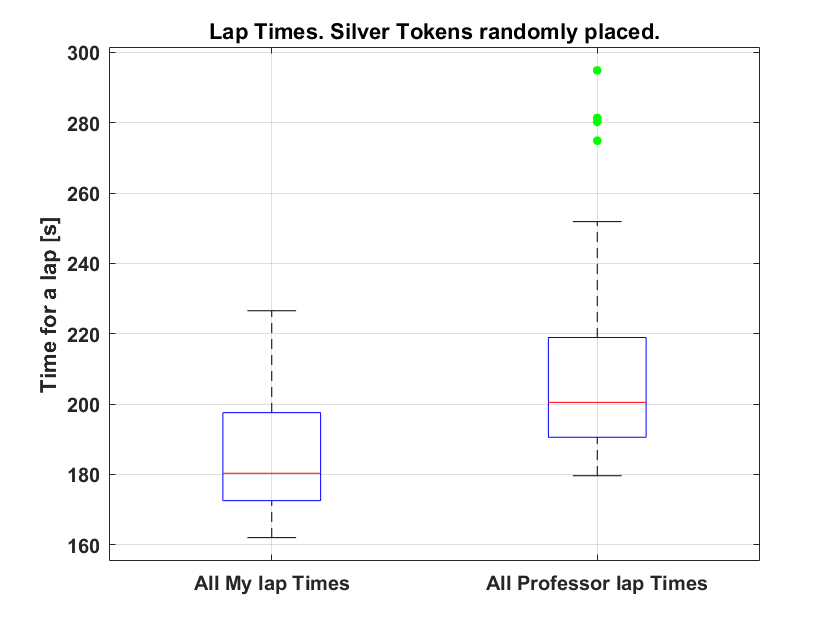

figure
boxplot([my_time_vector, sol_time_vector],'Symbol', 'g.', 'OutlierSize', 15, 'Widths', 0.3,  'Whisker',1.5);
grid on
ylabel("Time for a lap [s]")
if random == false
    title("Lap Times. Silver Tokens standardly placed.")
else
    title("Lap Times. Silver Tokens randomly placed.")
end
set(gca,'XTickLabel',{'All My lap Times', 'All Professor lap Times'},'fontweight','bold','fontsize',10);